# ENME462 Studio 4 Time Response

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM; Section 0103 F 10:00AM - 11:50AM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

The objective of this studio is to reinforce recetly learnt concepts of time response in the class.

## 1. First order system $G(s)=\frac{C(s)}{U(s)}=\frac{a}{s+a}$

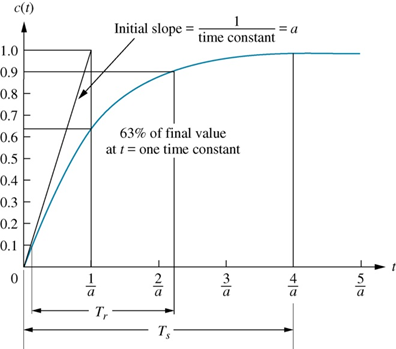

The specifications are defined for the unit step input.


$$C(s)=\frac{a}{s+a}\cdot\frac{1}{s}=\frac{1}{s}-\frac{1}{s+a}$$



$$c(t)=\mathcal{L}^{-1}\left(C(s)\right)=1-e^{-at}=1-e^{-t/\tau}$$


Time constant 


$$\tau=\frac{1}{a}$$


Initial slop


$$c\prime(t)=a\cdot e^{-at} \qquad c\prime(0)=a
$$


Rise time: time for the reponse to go from 0.1 to 0.9 of the steady state value.


$$c(2.31/a)=1-e^{-2.31}=0.9007 \\
c(0.11/a)=1-e^{-0.11}=0.1042\\
T_r=\frac{2.31}{a}-\frac{0.11}{a}=\frac{2.2}{a}$$


Settling time: time for the response to reach and stay within 2% of its final value.


$$c(4/a)=1-e^{-4}=0.9933 \\
T_s = 4/a$$


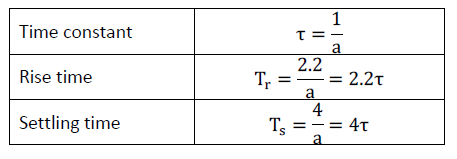

## 2. Second order system $G(s)=\frac{C(s)}{U(s)}=\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$  

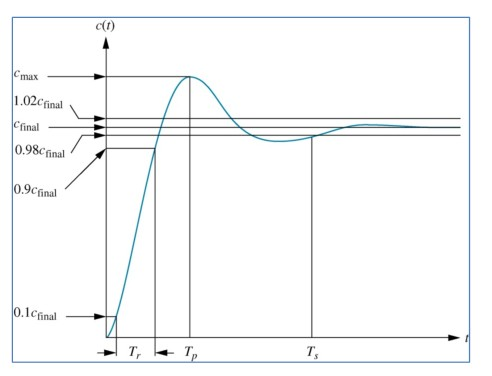

step response(under-damped)


$$C(s)=\frac{1}{s}\cdot\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}\\
=\frac{1}{s}-\frac{s+2\zeta \omega_{n}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}\\
=\frac{1}{s}-\frac{s+\zeta\omega_n}{(s+\zeta\omega_n)^{2}+\omega_d^2}-\frac{\zeta}{\sqrt{1-\zeta^2}}\cdot\frac{\omega_d}{(s+\zeta\omega_n)^{2}+\omega_d^2}$$
 


$$c(t)=\mathcal{L}^{-1}(C(s))=1-e^{-\zeta\omega_nt}\left(\cos(\omega_dt)+\frac{\zeta}{\sqrt{1-\zeta^2}}\sin(\omega_dt)\right)$$


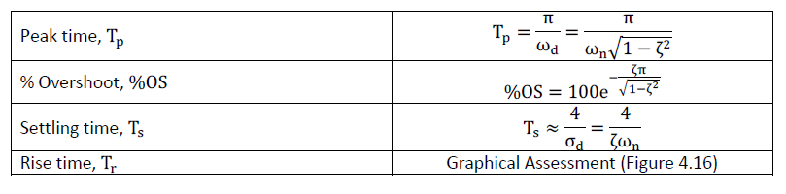

## 3. Antenna Control System:

What is the natural frequency, damping ratio, percentage of overshoot, and settling time for the open-loop response. Using a step response in MATLAB as computed in Studio1, these values will be verified.

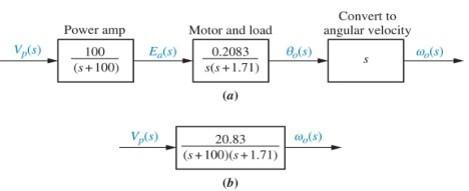

Transfer function:


$$G=\frac{20.83}{(s+100)(s+1.71)}=\frac{20.83}{s^2+101.7s+171}$$


For second order systems:


$$\frac{\omega_{n}^{2}}{s^2+2\zeta \omega_ns+\omega_{n}^{2}}$$


Natural frequency: $\omega_n=\sqrt{171}=13.08$

Damping ratio: $\zeta=\frac{2\zeta\omega_n}{2\omega_n}=\frac{101.7}{2\cdot13.08}=3.89$ (Over damped)

step response :


$$\omega_o(s)=\frac{1}{s}\cdot\frac{20.83}{(s+100)(s+1.71)}=\frac{0.122}{s}+\frac{2.12\cdot10^{-3}}{s+100}-\frac{0.124}{s+1.71}
$$



$$\omega_o=0.122+(2.12\cdot10^{-3})e^{-100t}-0.124e^{-1.71t}$$



$$a=1.71 \qquad T_s=\frac{4}{a}=\frac{4}{1.71}=2.34$$


G = zpk([],[-1.71,-100],20.83);
G = tf(G)


G =
 
         20.83
  -------------------
  s^2 + 101.7 s + 171
 
Continuous-time transfer function.



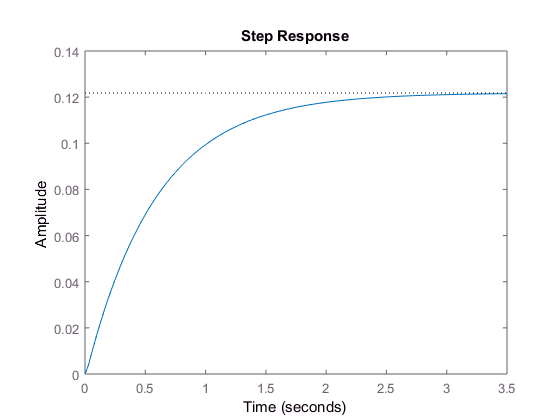

step(G)

stepinfo(G)

ans =         RiseTime: 1.2850
    SettlingTime: 2.2980
     SettlingMin: 0.1100
     SettlingMax: 0.1217
       Overshoot: 0
      Undershoot: 0
            Peak: 0.1217
        PeakTime: 4.2820


## 4. Unmanned Free-Swimming Submersible Vehicle - Open Loop Pitch presonse:

An UFSS and its corresponding pitch control system is shown in the figure below. the time response of the vehicle dyanmics that relates the pitch angle output to the elevator deflection input is studied now. 

a) Discuss the time response specifications using only second order poles.

b) Compute the pitch time response using both hand calculations and MATLAB.

c) Analyze the effect of the additional pole and zero in the system and judge whether the second order response can be appoximated for the system.

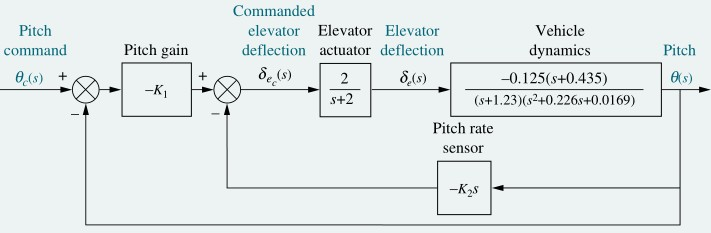

a) Second order poles only,


$$s^2+0.226s+0.0169\\
\omega_n^2=0.0169 \qquad 2\zeta\omega_n=0.226\\
\omega_n=0.13 \qquad \zeta=0.869 \qquad \omega_d=\sqrt{1-\zeta^2}\omega_n=0.0643$$


%Overshoot: $100\cdot e^{-\frac{\zeta\pi}{\sqrt{1-\zeta^2}}}=0.399\% \qquad T_p=\frac{\pi}{\omega_d}=48.9 \qquad=\frac{4}{\zeta\omega_n}=35.4$

b) Time response,


$$\theta(s)=\frac{0.125(s+0.435)}{s(s+1.23)(s^2+0.226s+0.0169)}\\
\theta(s)=2.62\frac{1}{s}+0.0645\frac{1}{s+1.23}-\frac{2.68(s+0.113)+3.478\sqrt{0.00413}}{(s+0.113)^2+0.00413}$$



$$\theta(t)=2.62+0.0645e^{-1.23t}-e^{-0.113t}(2.68\cos0.0643t+3.478\sin0.0643t)$$


syms s % Construct symbolic object for Laplace variable 's'.
num = 0.125 * (s+0.435);
den = s * (s+1.23) * (s^2 + 0.226*s + 0.0169);
theta = ilaplace(num/den); % inverse Laplace transformation
theta = vpa(theta,3) % Convert symbolic numerical fractions to 3-place decimal representation.

$$theta = 0.0645\,{\mathrm{e}}^{-1.23\,t}-2.68\,{\mathrm{e}}^{-0.113\,t}\,\left(\cos\left(0.0643\,t\right)+1.3\,\sin\left(0.0643\,t\right)\right)+2.62$$


nump = sym2poly(num);
denp = sym2poly(den);
[r,p,k] = residue(nump,denp) % Calculate residues, poles, and direct quotient.

r =    0.0645 + 0.0000i
  -1.3402 + 1.7387i
  -1.3402 - 1.7387i
   2.6158 + 0.0000i


p =   -1.2300 + 0.0000i
  -0.1130 + 0.0643i
  -0.1130 - 0.0643i
   0.0000 + 0.0000i


k = []

c)

s= zpk('s') % Construct symbolic object for Laplace variable 's'.


s =
 
  s
 
Continuous-time zero/pole/gain model.



num = 0.125 * (s+0.435);
den = (s+1.23) * (s^2 + 0.226*s + 0.0169);
G = num/den


G =
 
          0.125 (s+0.435)
  --------------------------------
  (s+1.23) (s^2 + 0.226s + 0.0169)
 
Continuous-time zero/pole/gain model.



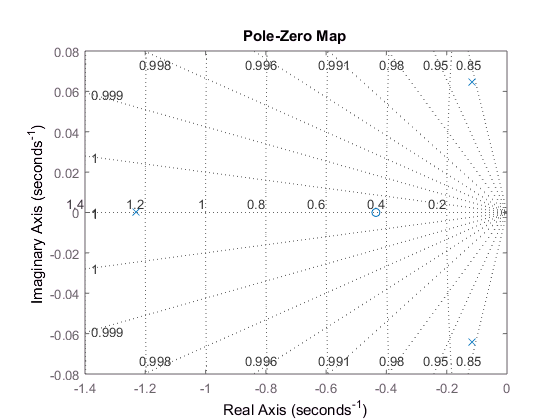

pzmap(G)
grid on

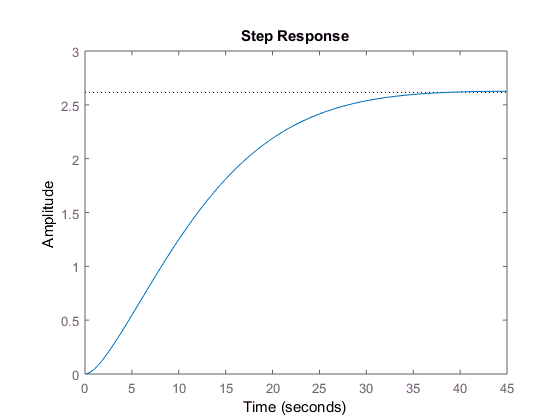

step(G)

stepinfo(G)

ans =         RiseTime: 20.3983
    SettlingTime: 31.7417
     SettlingMin: 2.3660
     SettlingMax: 2.6269
       Overshoot: 0.4233
      Undershoot: 0
            Peak: 2.6269
        PeakTime: 46.8668


## MATLAB Exercises

**Exercises 1.** For the UFSS system studied in Part 4, use MATLAB to compute the unit step open-loop response of the transfer function between pitch angle output to the elevator deflection input. Then using the plot, compute the percentage overshoot, rise time, peak time, settling time and compare them with the theoretical predictions. Show these values on the plot as well.

**Exercises 2.** Several factors affect the working of the kidneys. The figure below shows how a step change in arterial flow pressure affects renal blood flow in rats. In the "hot tail" part of the experiment, peripheral thermal receptor simulation is achieved by inserting the rat's tail in heated water. The vertical lines indicate variations between different test subjects. It has been argued and asserted in the literature that the "control" and "hot tail" responses are identical expect their steady state values.

a) Use figure below, obtain the normalized(c_final = 1) transfer function for both responses.

b) Use MATLAB to prove or disprove the assertion about the "control" and "hot-tail" responses.